clear; clc;

% Parámetros iniciales
x = 0; y = 0; theta = 0;

% Historial de pasos
v = [1.432, 0.0, 1.432, 0.0, 1.432, 0.0, 1.432, 0.0, 1.432, 0.0];
w = [0.0, 2.513, 0.0, 2.513, 0.0, 2.513, 0.0, 2.513, 0.0, 2.513];
dt = ones(1, 10);
N = length(v);

% Inicializamos almacenamiento
x1 = zeros(1, N+1);
y1 = zeros(1, N+1);
phi = zeros(1, N+1); % orientación

% Pose inicial
x1(1) = x; y1(1) = y; phi(1) = theta;

% Cálculo de la pose paso a paso
for k = 1:N
    x = x + v(k) * cos(theta) * dt(k);
    y = y + v(k) * sin(theta) * dt(k);
    theta = theta + w(k) * dt(k);
    
    x1(k+1) = x;
    y1(k+1) = y;
    phi(k+1) = theta;
end


T = table((1:10)', x1(2:end)', y1(2:end)', phi(2:end)', ...
    'VariableNames', {'Paso', 'x', 'y', 'theta_rad'});
disp(T);

    Paso         x             y         theta_rad
    ____    ___________    __________    _________

      1           1.432             0          0  
      2           1.432             0      2.513  
      3         0.27372       0.84203      2.513  
      4         0.27372       0.84203      5.026  
      5         0.71548      -0.52013      5.026  
      6         0.71548      -0.52013      7.539  
      7          1.1591       0.84142      7.539  
      8          1.1591       0.84142     10.052  
      9     -0.00031834    0.00098158     10.052  
     10     -0.00031834    0.00098158     12.565  




% Pose final
pose_final = [x, y, theta];
fprintf('\nPose final del robot tras 10 pasos:\n');


Pose final del robot tras 10 pasos:


fprintf('x = %.3f m\ny = %.3f m\ntheta = %.3f rad (%.2f°)\n', ...
    pose_final(1), pose_final(2), pose_final(3), rad2deg(pose_final(3)));

x = -0.000 m
y = 0.001 m
theta = 12.565 rad (719.92°)



% ---- Animación 3D ----
hx = x1; hy = y1; ts = 1;

scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'Position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([135 35]);
axis([-7 7 -2 10 0 2]);

scale = 4;
MobileRobot_5;  % Robot 3D
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);

for k = 2:N+1
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end


pose 2

%% Ejercicio 2 
clear; close all; clc;

% Parámetros físicos del robot diferencial
radioRueda = 0.05;    % Radio de la rueda (m)
distanciaEjes = 0.18; % Distancia entre ruedas (m)
pasoTiempo = 1.0;    % Paso de simulación (s)

% Lecturas de velocidades angulares
velAngDerecha = [4.582, 4.773, 5.291, 5.960, 6.490, ...
                -1.168, -1.364, 5.960, 5.291, 4.773, ...
                 4.582, 4.773, 5.291, 5.960, 6.490, ...
                 6.686, 6.490, 5.960, 5.291, 4.773, 4.582];

velAngIzquierda = [1.701, 2.353, 3.676, 4.856, 5.618, ...
                  13.735, 13.472, 4.856, 3.676, 2.353, ...
                   1.701, 2.353, 3.676, 4.856, 5.618, ...
                   5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

numPasos = length(velAngDerecha);

% Inicialización
velLineal = zeros(1, numPasos);
velAngular = zeros(1, numPasos);
posX = zeros(1, numPasos + 1);
posY = zeros(1, numPasos + 1);
orientacion = zeros(1, numPasos + 1);

hx = zeros(1, numPasos + 1);
hy = zeros(1, numPasos + 1);

% Cálculo de la trayectoria
for paso = 1:numPasos
    velLineal(paso) = (radioRueda / 2) * (velAngDerecha(paso) + velAngIzquierda(paso));
    velAngular(paso) = (radioRueda / distanciaEjes) * (velAngDerecha(paso) - velAngIzquierda(paso));

    orientacion(paso + 1) = orientacion(paso) + velAngular(paso) * pasoTiempo;
    orientacion(paso + 1) = atan2(sin(orientacion(paso + 1)), cos(orientacion(paso + 1)));

    posX(paso + 1) = posX(paso) + velLineal(paso) * cos(orientacion(paso + 1)) * pasoTiempo;
    posY(paso + 1) = posY(paso) + velLineal(paso) * sin(orientacion(paso + 1)) * pasoTiempo;

    hx(paso + 1) = posX(paso + 1);
    hy(paso + 1) = posY(paso + 1);
end

% Tabla de resultados
tablaPaso2 = table((0:numPasos)', ...
    [velLineal, NaN]', ...
    [velAngular, NaN]', ...
    [velAngDerecha, NaN]', ...
    [velAngIzquierda, NaN]', ...
    posX', posY', rad2deg(orientacion)', ...
    'VariableNames', {'t_s', 'v_mps', 'w_rps', 'omega_R', 'omega_L', 'x_m', 'y_m', 'theta_deg'});

disp(tablaPaso2);

    t_s     v_mps      w_rps     omega_R    omega_L       x_m         y_m        theta_deg 
    ___    _______    _______    _______    _______    _________    ________    ___________

     0     0.15707    0.80028     4.582      1.701             0           0              0
     1     0.17815    0.67222     4.773      2.353        0.1094     0.11271         45.853
     2     0.22418    0.44861     5.291      3.676       0.12689        0.29         84.368
     3      0.2704    0.30667      5.96      4.856      0.049952     0.50056         110.07
     4      0.3027    0.24222      6.49      5.618      -0.11519     0.71467         127.64
     5     0.31418    -4.1397    -1.168     13.735      -0.35215     0.90302       

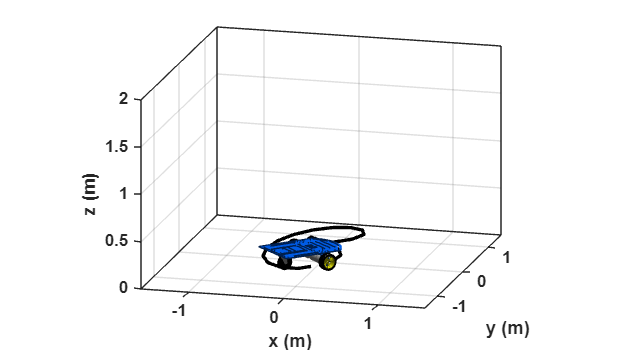


% ---------------- SIMULACIÓN 3D ----------------
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
view([15 15]);
axis([-1.5 1.5 -1.5 1.5 0 2]); % Ajusta si lo necesitas

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(posX(1), posY(1), orientacion(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 1;
for k = 1:step:numPasos+1
    delete(H1);    
    delete(H2);
    H1 = MobilePlot_4(posX(k), posY(k), orientacion(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'k ', 'lineWidth', 2);
    pause(pasoTiempo);
end

pose 3

clear; clc;

% Parámetros del robot
r = 0.05;       % Radio de rueda (m)
L = 0.18;       % Distancia entre ruedas (m)
dt = 1.0;       % Paso de tiempo (s)
R = 15;         % Radio de la trayectoria circular (m)
v = 1.0;        % Velocidad lineal (m/s)

% Cálculo de velocidad angular del robot
w = v / R;

% Velocidades angulares de las ruedas
omegaR = (2*v + w*L) / (2*r);
omegaL = (2*v - w*L) / (2*r);

% Simulación por 96 pasos (equivalente a una vuelta de 2pi rad)
N = round(2*pi*R / (v*dt)); % Total de pasos para una vuelta

% Inicialización de vectores de pose
xr = zeros(1, N+1);
yr = zeros(1, N+1);
thetar = zeros(1, N+1); % Ángulo en radianes

% Simulación
for k = 1:N
    thetar(k+1) = thetar(k) + w * dt;
    xr(k+1) = xr(k) + v * cos(thetar(k)) * dt;
    yr(k+1) = yr(k) + v * sin(thetar(k)) * dt;
end

% Mostrar tabla de velocidades
omegaR_arr = omegaR * ones(1, N);
omegaL_arr = omegaL * ones(1, N);
tabla = table((1:N)', omegaR_arr', omegaL_arr', 'VariableNames', {'Paso','w_R','w_L'});

% Mostrar resultados
disp(tabla);

    Paso     w_R      w_L 
    ____    _____    _____

      1     20.12    19.88
      2     20.12    19.88
      3     20.12    19.88
      4     20.12    19.88
      5     20.12    19.88
      6     20.12    19.88
      7     20.12    19.88
      8     20.12    19.88
      9     20.12    19.88
     10     20.12    19.88
     11     20.12    19.88
     12     20.12    19.88
     13     20.12    19.88
     14     20.12    19.88
     15     20.12    19.88
     16     20.12    19.88
     17     20.12    19.88
     18     20.12    19.88
     19     20.12    19.88
     20     20.12    19.88
     21     20.12    19.88
     22     20.12    19.88
     23     20.12    19.88
     24     20.12    19.88
     25     20.12    19.88
     26     20.12    19.88
     27     20.12    19.88
     28     20.12    19.88
     29     20.12    19.88
     30     20.12    19.88
     31     20.12    19.88
     3

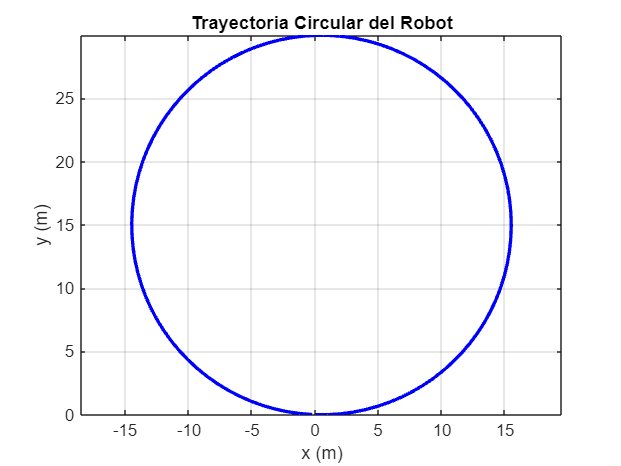


% Graficar trayectoria
figure;
plot(xr, yr, 'b', 'LineWidth', 2);
axis equal;
xlabel('x (m)');
ylabel('y (m)');
title('Trayectoria Circular del Robot');
grid on;